The first 3 files are for Wesley, the next 3 are for Elvis, and the last 3 are for Melissa. At first we had 6 balls to hit per file, but we later had only 5. All swings were forehand. Data was recorded at 100Hz.

Because there is rotation, it is important to have the orientation data so we can translate back to the global coordinate system.

First, load in all the data files and pick out the individual hits.

There is a signficant amount of extra data at the start because we had to fit the phone into the armband and setup each time. We can remove this off the bat to make it easier to identify the individual hits.

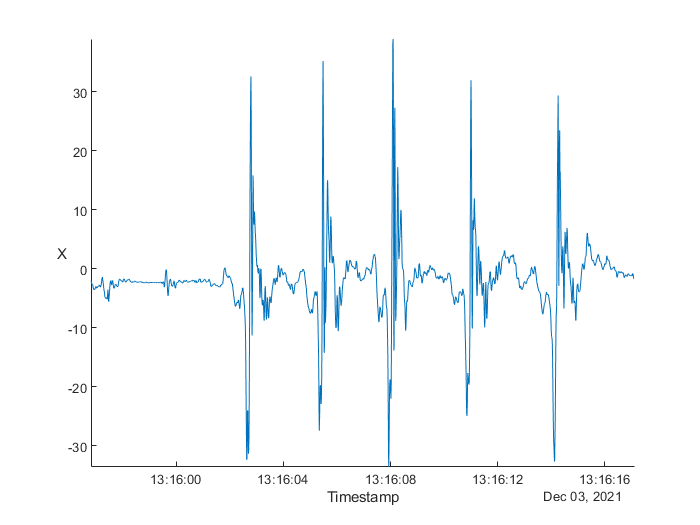

clear;
load data\data8.mat
% plot overything so we can get a sense of what our data looks like
% once we figure it out for one sample, we can trim the others and repeat
%TODO: label
% if we have time it would be cool to ffmpeg the video into frames and then
% plot on top
% trim to get one shot
% for data4:
%shot1 = timerange("03-Dec-2021 13:07:50.828","03-Dec-2021 13:07:52.886");
% for data8
shot1 = timerange("03-Dec-2021 13:16:01.567","03-Dec-2021 13:16:04.371");
% show the whole thing for trimming
stackedplot(Acceleration(:,"X"))

Acceleration = Acceleration(shot1, :);
Orientation = Orientation(shot1, :);

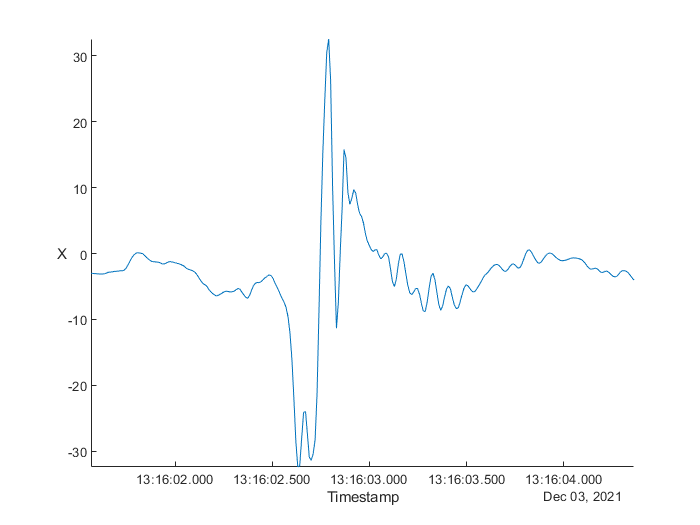

stackedplot(Acceleration(:,"X"))

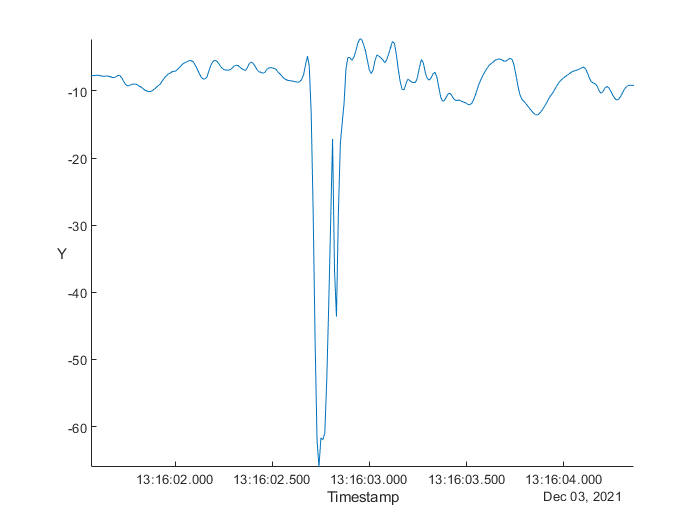

stackedplot(Acceleration(:,"Y"))

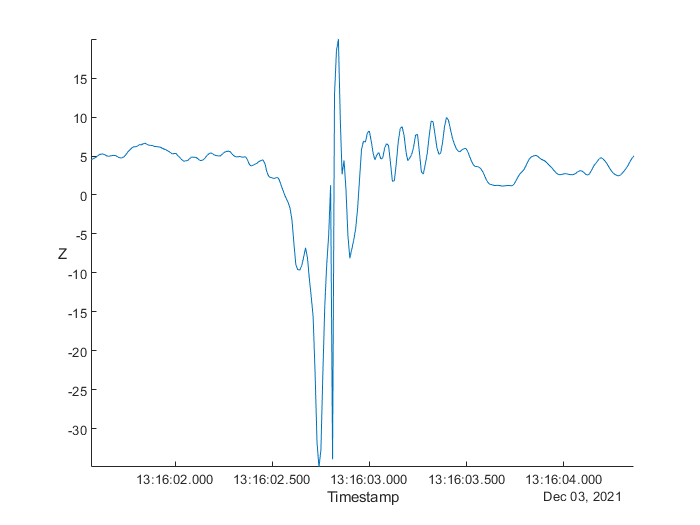

stackedplot(Acceleration(:,"Z"))

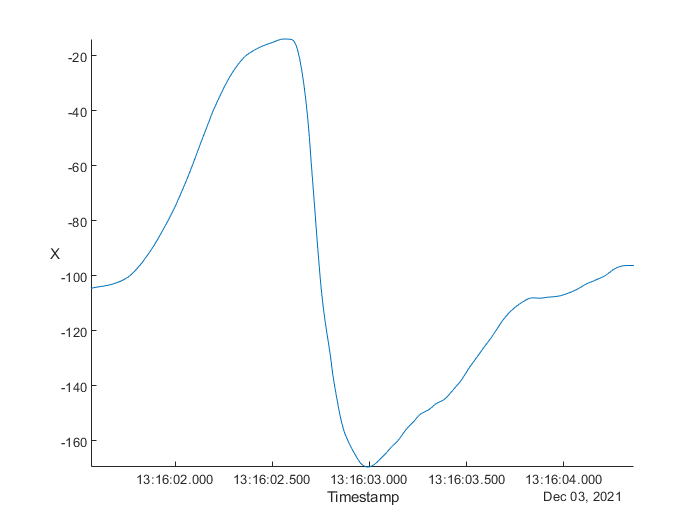

stackedplot(Orientation(:,"X"))

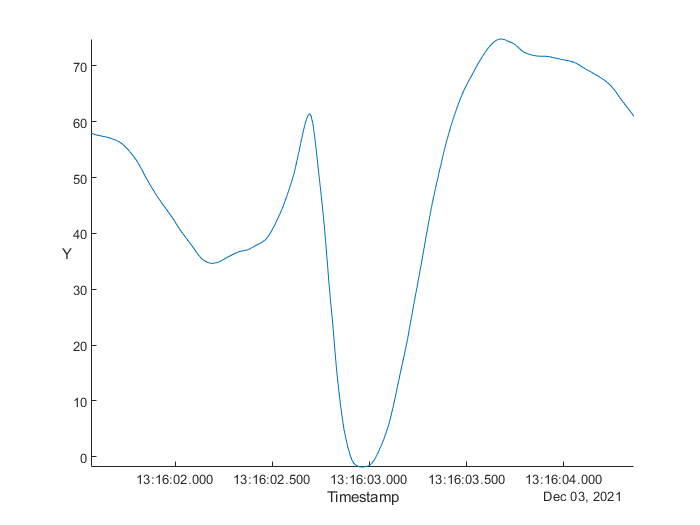

stackedplot(Orientation(:,"Y"))

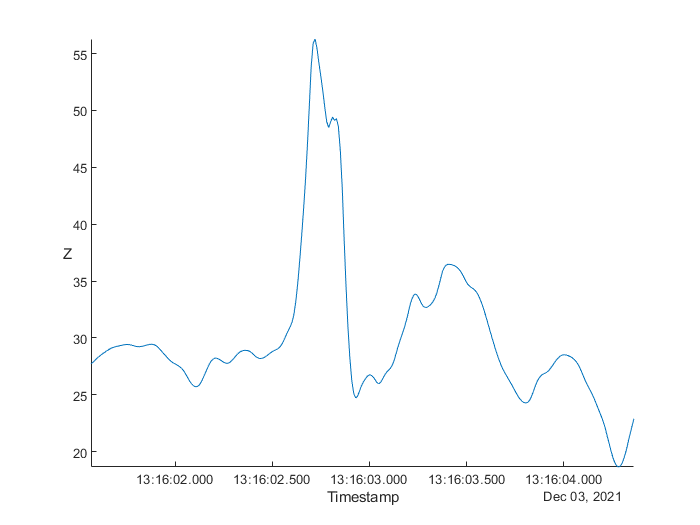

stackedplot(Orientation(:,"Z"))

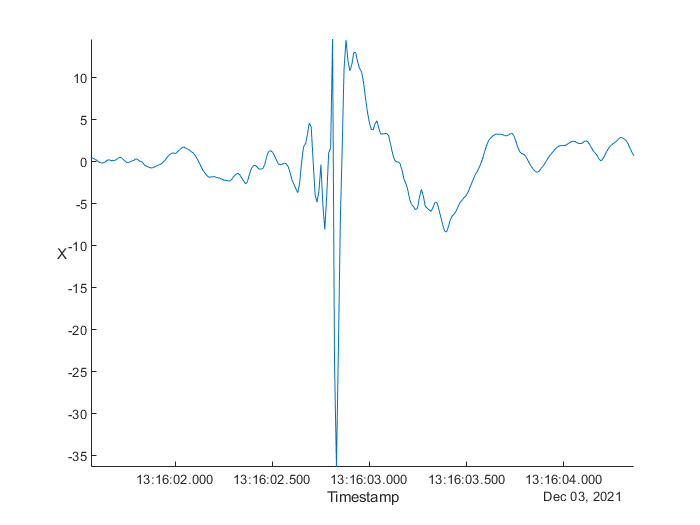


% normalize the data by projecting into gloabal coordinates and filtering
Accel = normalize_acceleration(Acceleration, Orientation, 0, 1/4);
stackedplot(Accel(:,"X"))

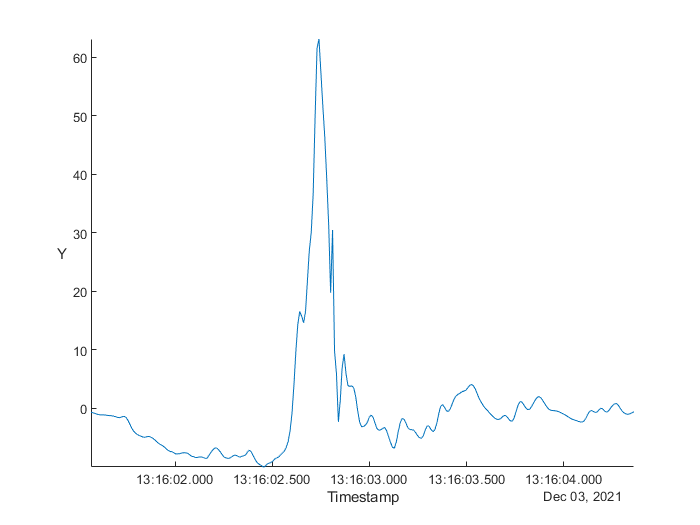

stackedplot(Accel(:,"Y"))

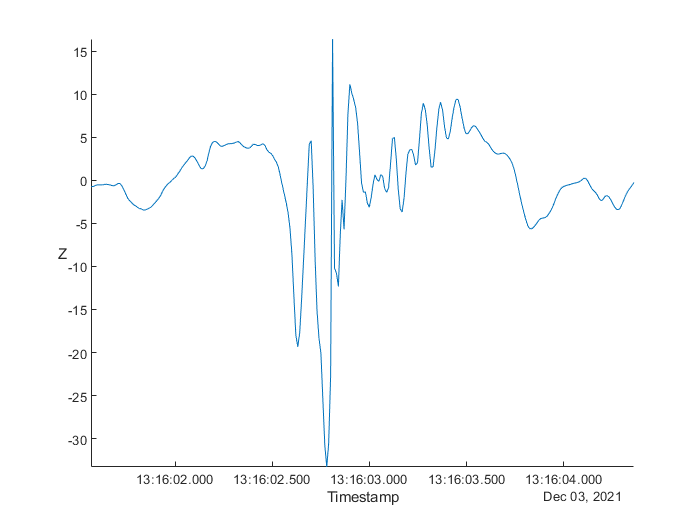

stackedplot(Accel(:,"Z"))

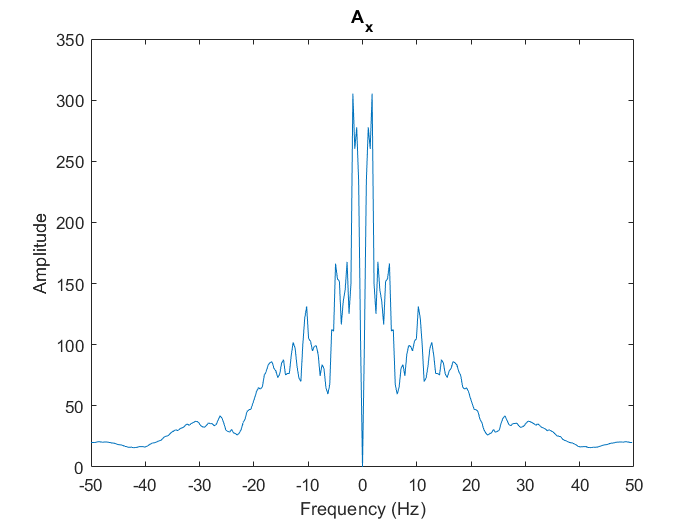

% fft now that we have all our positional information
a_mat = Accel.Variables;

[freqs, freq_domain] = hz_fft(a_mat(:, 1), 100);
plot_fft(freqs, freq_domain, "A_x");

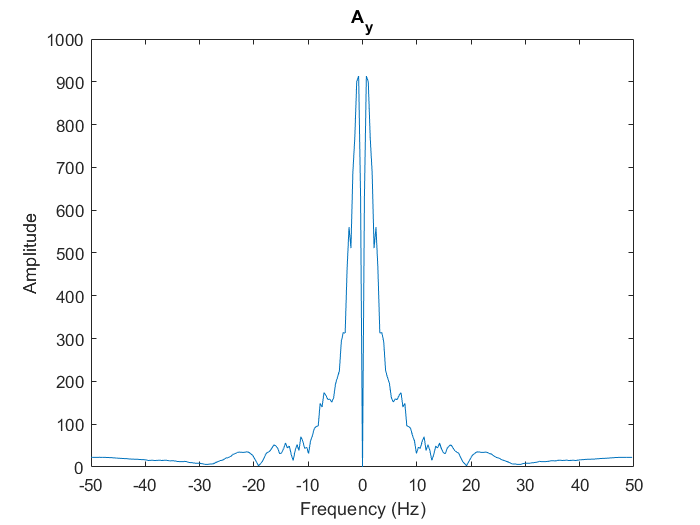

[freqs, freq_domain] = hz_fft(a_mat(:, 2), 100);
plot_fft(freqs, freq_domain, "A_y");

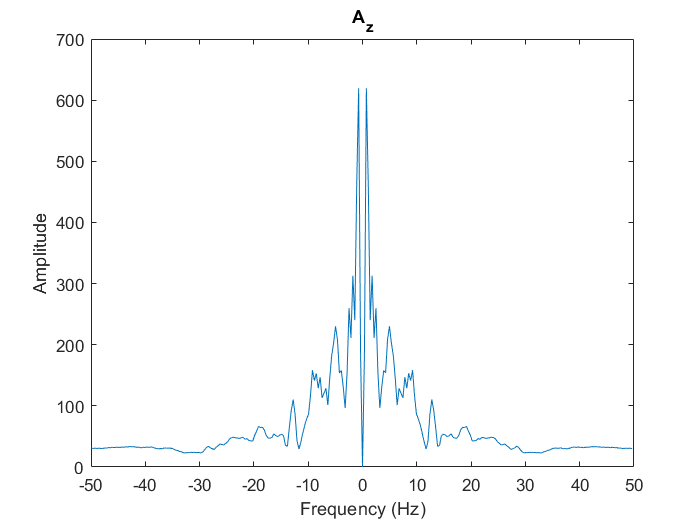

[freqs, freq_domain] = hz_fft(a_mat(:, 3), 100);
plot_fft(freqs, freq_domain, "A_z");

o_mat = Orientation.Variables;
% [freqs, freq_domain] = hz_fft(o_mat(:, 1), 100);
% plot_fft(freqs, freq_domain, "O_x");
% [freqs, freq_domain] = hz_fft(o_mat(:, 2), 100);
% plot_fft(freqs, freq_domain, "O_y");
% [freqs, freq_domain] = hz_fft(o_mat(:, 3), 100);
% plot_fft(freqs, freq_domain, "O_z");

mean(a_mat(:, 3))

ans = -0.1559

% integrate for velocity
Velocity = integrate_tt(Accel);
v_mat = Velocity.Variables;

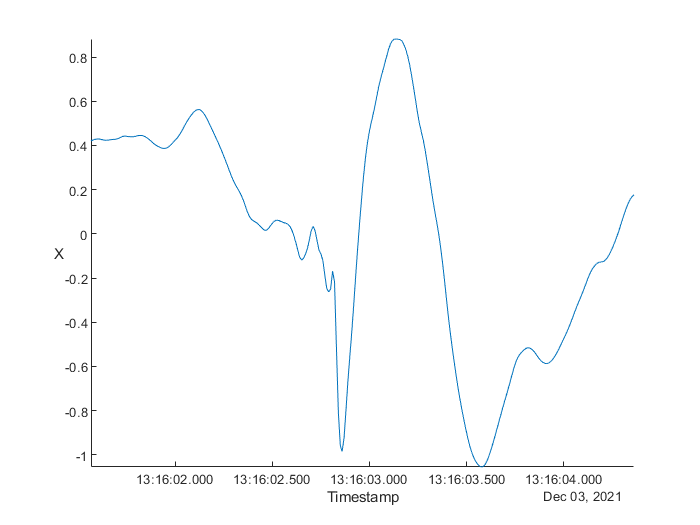

stackedplot(Velocity(:,"X"))

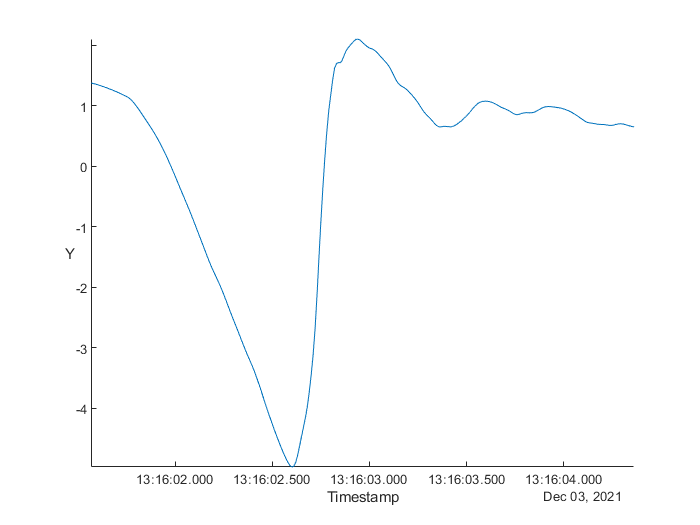

stackedplot(Velocity(:,"Y"))

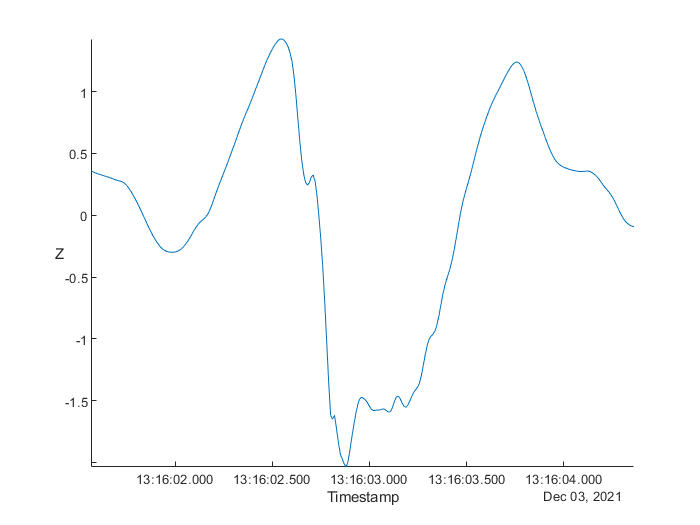

stackedplot(Velocity(:,"Z"))

% max speed
max(abs(vecnorm(v_mat)))

ans = 31.7738

% integrate again for position
Position = integrate_tt(Velocity);
p_mat = Position.Variables;

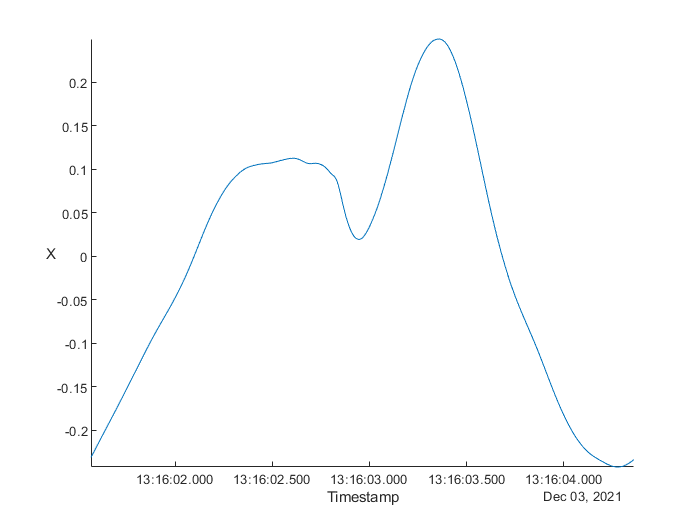

stackedplot(Position(:,"X"))

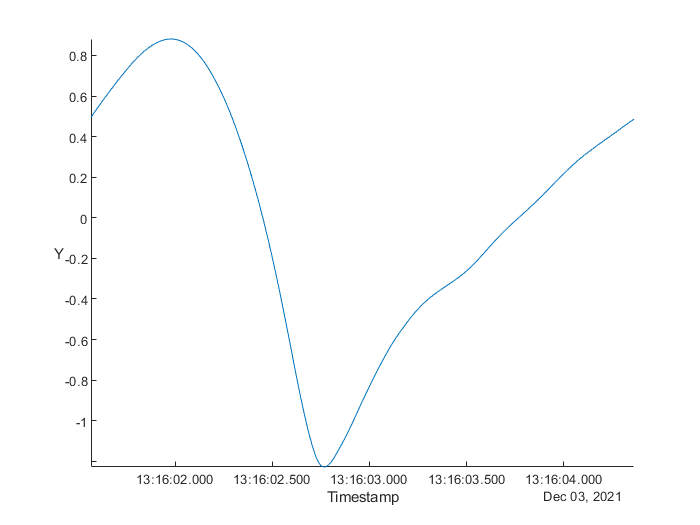

stackedplot(Position(:,"Y"))

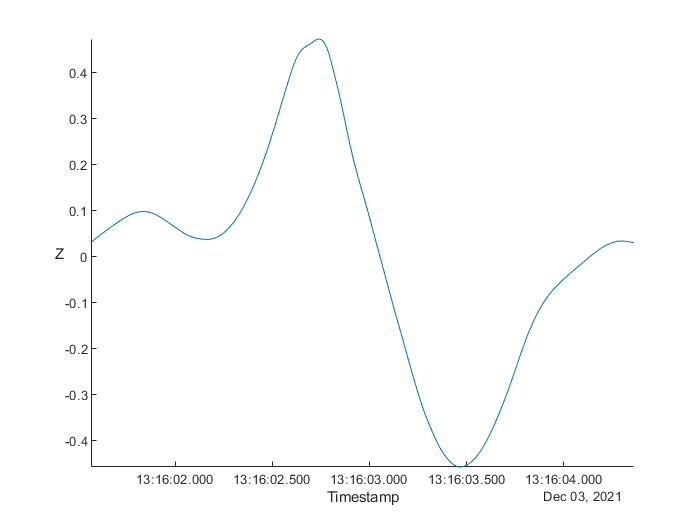

stackedplot(Position(:,"Z"))

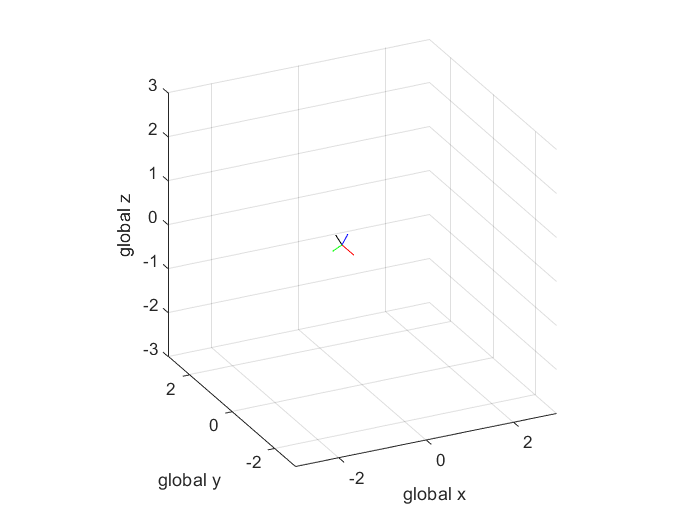

%TODO: visualize the position and velocity and acceleration vectors
% visualize the orientation over time
figure();
% current position
x = 0; y = 0; z = 0;
% plot the orientation vectors
BASIS = [ 
    1 0 0;
    0 1 0;
    0 0 1;
];
points = height(Accel);
orientation_matrix = Orientation.Variables;
for idx=1:points % skip points to speedup and keep animation realtime (remove later!)
    clf;
    R = rot(orientation_matrix(idx, :));
    V = R * BASIS;
    V = V * 1/3; % manually scale arrow down
    velocity = v_mat(idx, :);
    position = p_mat(idx, :);
    hold on;
    quiver3(position(1), position(2), position(3), V(1,1), V(1,2), V(1,3), 0, 'r');
    quiver3(position(1), position(2), position(3), V(2,1), V(2,2), V(2,3), 0, 'b');
    quiver3(position(1), position(2), position(3), V(3,1), V(3,2), V(3,3), 0, 'g');
    quiver3(position(1), position(2), position(3), velocity(1), velocity(2), velocity(3), 0, 'k');
    hold off;
    axis equal;
    lim = 3;
    limit = [-lim, lim];
    xlim(limit);
    ylim(limit);
    zlim(limit);
    xlabel("global x")
    ylabel("global y")
    zlabel("global z")
    grid on;
    view([-26, 25]);
    drawnow; %limitrate % run at 20fps, remove this for exporting to video
end



% maybe looking at upwards acceleration would allow us to evaluate spin?
% can probably get angle at impact
% maybe could get some sample data to show we can score low for having a
% really bad angle

% https://www.mathworks.com/matlabcentral/fileexchange/23629-export_fig
% might work for saving as a transparent overlay for video
% otherwise can just live with the white background

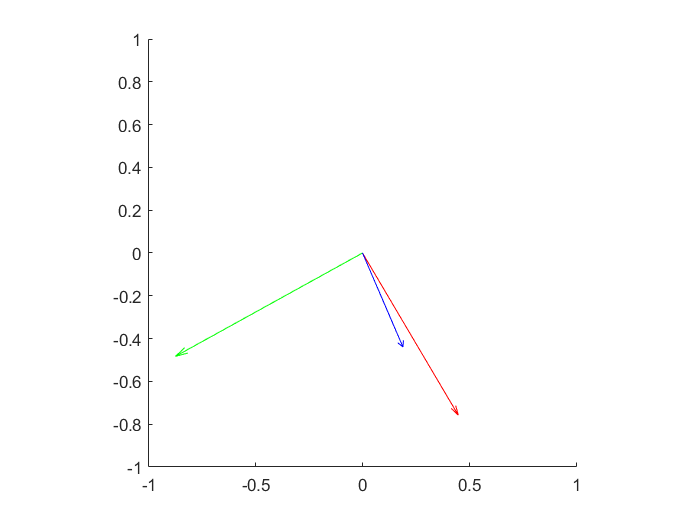

% visualize the orientation over time
figure();
% current position
x = 0; y = 0; z = 0;
% plot the orientation vectors
BASIS = [ 
    1 0 0;
    0 1 0;
    0 0 1;
];
points = height(Accel);
position = [x, y, z];
orientation_matrix = Orientation.Variables;
for idx=1:points % skip points to speedup and keep animation realtime (remove later!)
    clf;
    R = rot(orientation_matrix(idx, :));
    V = R * BASIS;
    hold on;
    quiver3(position(1), position(2), position(3), V(1,1), V(1,2), V(1,3), 0, 'r');
    quiver3(position(1), position(2), position(3), V(2,1), V(2,2), V(2,3), 0, 'b');
    quiver3(position(1), position(2), position(3), V(3,1), V(3,2), V(3,3), 0, 'g');
    hold off;
    axis equal;
    xlim([-1, 1]);
    ylim([-1, 1]);
    zlim([-1, 1]);
    drawnow; %limitrate % run at 20fps, remove this for exporting to video
end

function R = rot(angle)
    R = rotz(angle(3)) * roty(angle(2)) * rotx(angle(1));
end

% take the acceleration and orientation data and transform the axis to the
% global system
function A = normalize_acceleration(accel, orient, g, fpass)
    % unfortunately because orientation is changing we have to transform
    % row by row instead of just using a single matrix multiplication
    vectors = accel.Variables;
    orientation_vectors = orient.Variables;
    for i=1:height(accel)
        vector = vectors(i, :);
        % now that we don't need it anymore overwrite it
        vectors(i, :) = vector * rot(orientation_vectors(i, :));
    end
    Timestamp = accel.Timestamp; % get the times for creating a new timetable
    % remove gravity
    vectors(:, 3) = vectors(:, 3) + g;
    % because the person may be drifting (moving overall)
    % and we expect the arm position to more or less return to the start
    % we are just using a high pass filter to do so
    vectors = filter_acceleration(vectors, fpass);
    % they should also be mean centered to prevent drift
    A = timetable(Timestamp, vectors(:, 1), vectors(:, 2), vectors(:, 3), 'VariableNames',{'X','Y', 'Z'});
end

function A =  filter_acceleration(accel_mat, fpass)
    % high pass filter on each dimension
    accel_mat(:, 1) = highpass(accel_mat(:, 1), fpass, 100);
    accel_mat(:, 2) = highpass(accel_mat(:, 2), fpass, 100);
    accel_mat(:, 3) = highpass(accel_mat(:, 3), fpass, 100);
    A = accel_mat;
end

function integ = integrate_tt(accel)
    % integrate
    vectors = accel.Variables;
    Timestamp = accel.Timestamp;
    t = seconds(accel.Timestamp - accel.Timestamp(1));
    integrated = cumtrapz(t, vectors);
    % we don't have our integration constant, because we are looking at a
    % cycle of motion zero centering should be safe
    integrated = zero_center(integrated);
    integ = timetable(Timestamp, integrated(:, 1), integrated(:, 2), integrated(:, 3), 'VariableNames',{'X','Y', 'Z'});    
end

function filtered = fft_highpass(signal, Fs, Fpass, strength)
    y = signal;
    N = length(y);
    freqs = linspace(-Fs*pi , Fs*(pi - 2*pi/N), N) + Fs*pi/N*mod(N,2);
    freqs = freqs * (1/(2*pi));
    freq_domain = fftshift(fft(y));
    % remove low frequencies
    filter_out = freqs > -Fpass && freqs < Fpass;
    % make it smooth (not a sharp cut) by increasing weight farther away
    % using exponential should give beahvior like what you see with an RC
    % filter
    filter_weights = exp(abs(freqs) - Fpass);
    weights = filter_weights(filter_out); % get just the weights that will be used
    % make a copy of the data
    freq_domain_filtered = freq_domain;
    % applt the filter
    freq_domain_filtered(filter_out) = freq_domain(filter_out)/(weights * strength);
    % go back to the time domain
    filtered = ifft(ifftshift(freq_domain_filtered));
end

function [freqs, freq_domain] = hz_fft(signal, Fs)
    y = signal;
    N = length(y);
    freqs = linspace(-Fs*pi , Fs*(pi - 2*pi/N), N) + Fs*pi/N*mod(N,2);
    freqs = freqs * (1/(2*pi));
    freq_domain_unfiltered = fftshift(fft(y));
    freq_domain_unfiltered(abs(freqs) < 1e-5) = 0; % remove 0 peak for display
    freq_domain = freq_domain_unfiltered;
end

% just to help keep the livescript clean
function [] = plot_fft(freqs, freq_domain, chart_title)
    figure()
    plot(freqs, abs(freq_domain));
    title(chart_title);
    ylabel("Amplitude")
    xlabel("Frequency (Hz)")
end

function centered = zero_center(vectors)
    vectors(:, 1) = vectors(:, 1) - mean(vectors(:, 1));
    vectors(:, 2) = vectors(:, 2) - mean(vectors(:, 2));
    vectors(:, 3) = vectors(:, 3) - mean(vectors(:, 3));
    centered = vectors;
end